Funzione di Runge

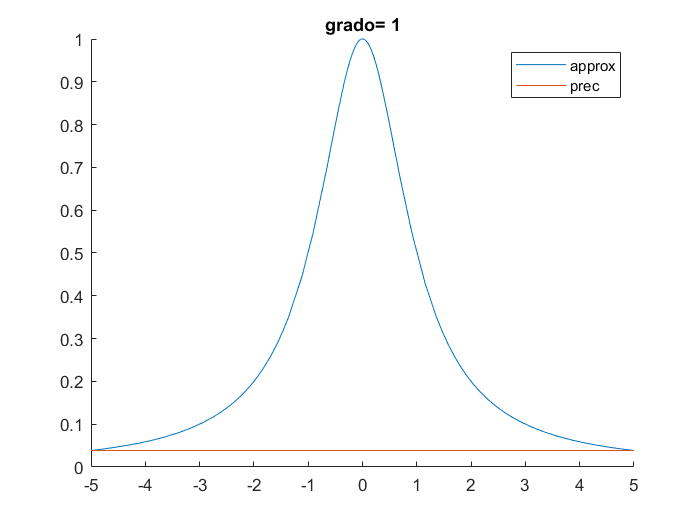

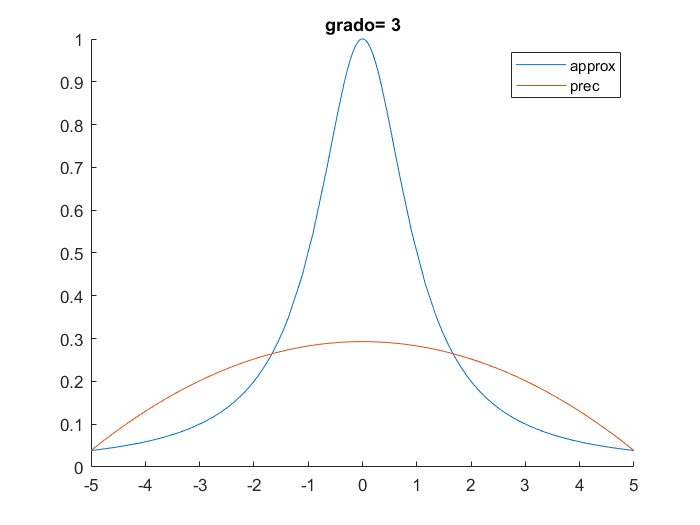

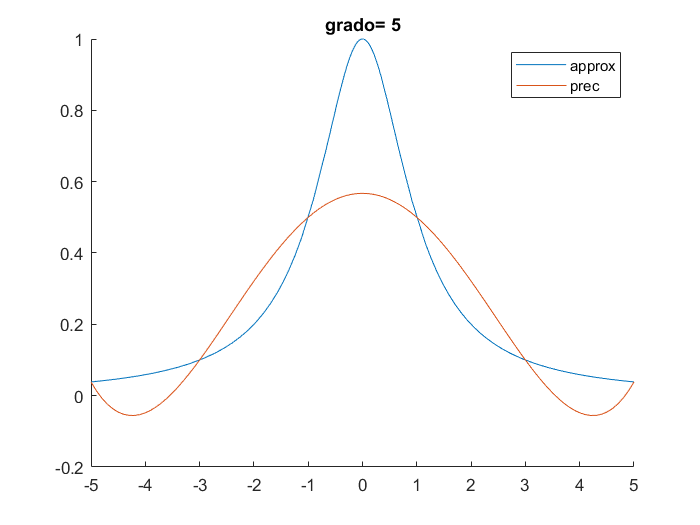

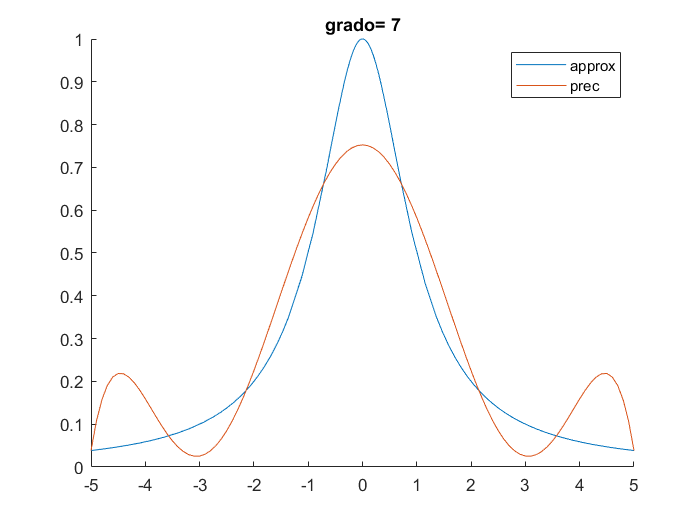

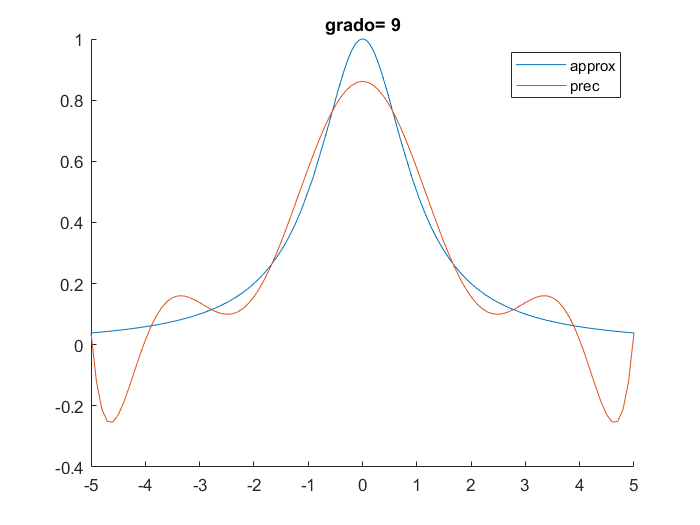

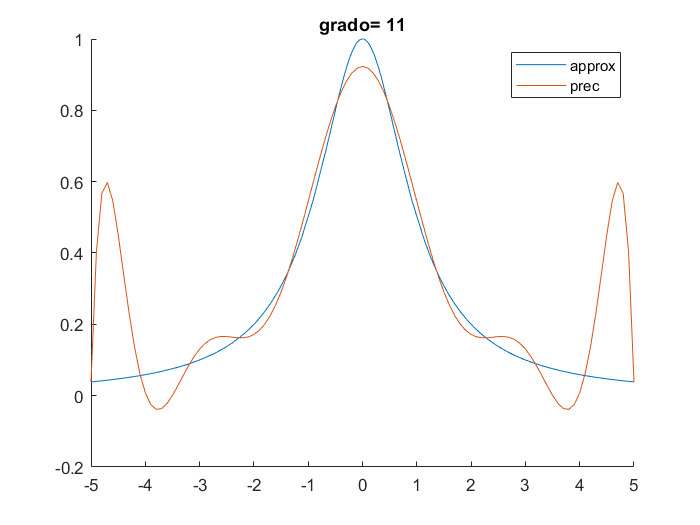

clear all
f=@(x) 1./(1+x.^2);
N=100;
X=linspace(-5,5,N);
fn=f(X);
err1=[];
for V=1:2:12
    figure()
    hold on
    title(['grado= ',num2str(V)])
    fplot(f,[-5 5])
    x=linspace(-5,5,V+1);
    y=f(x);
    p=polyfit(x,y,V);
    x1=-5:0.1:5;
    y=polyval(p,x1);
    plot(x1,y)
    e=polyval(p,X);
    e=norm(fn-e,"inf");
    err1=[err1 e];
    legend("approx","prec")
end

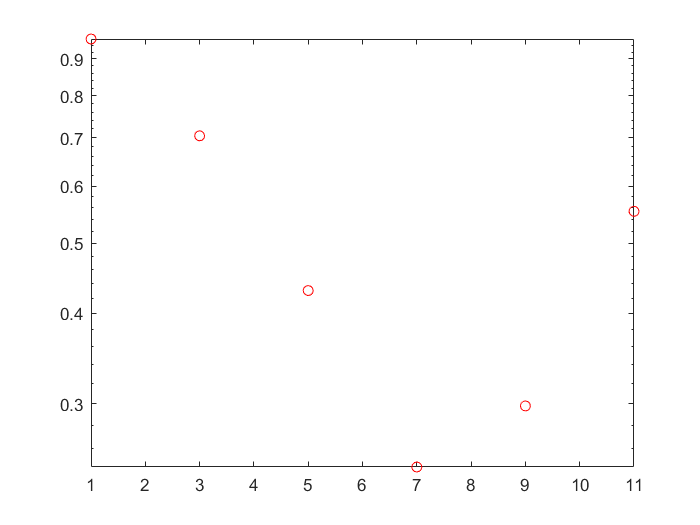

figure()
semilogy(1:2:12,err1,"or")

con nodi di chevishev

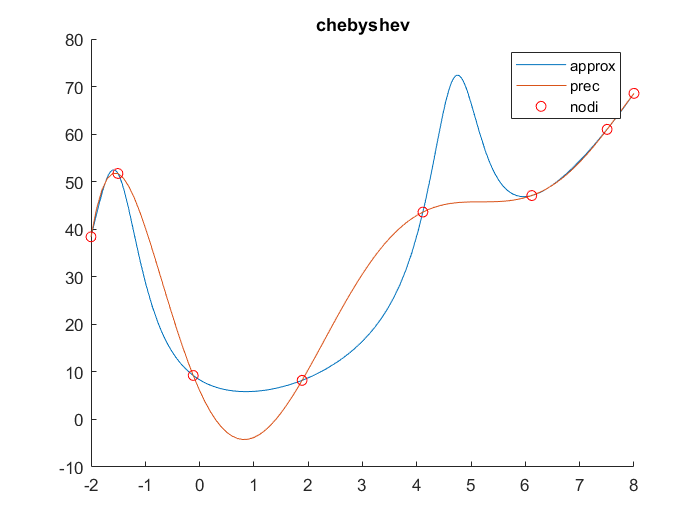

clear
f=@(x) x.^2+10./(sin(x)+1.2);
n=7;
a=-2;
b=8;
xc=(a+b)/2-(b-a)/2*cos(pi*(0:n)/n);
N=100;
fn=f(xc);
figure()
hold on
title('chebyshev')
fplot(f,[a b])
p=polyfit(xc,fn,n);
x1=a:0.1:b;
y=polyval(p,x1);
plot(x1,y)
plot(xc,fn,'or')
legend("approx","prec","nodi")

es 7

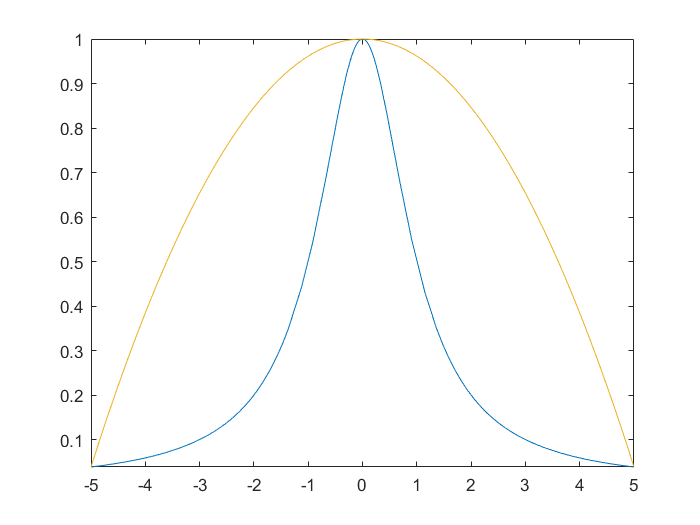

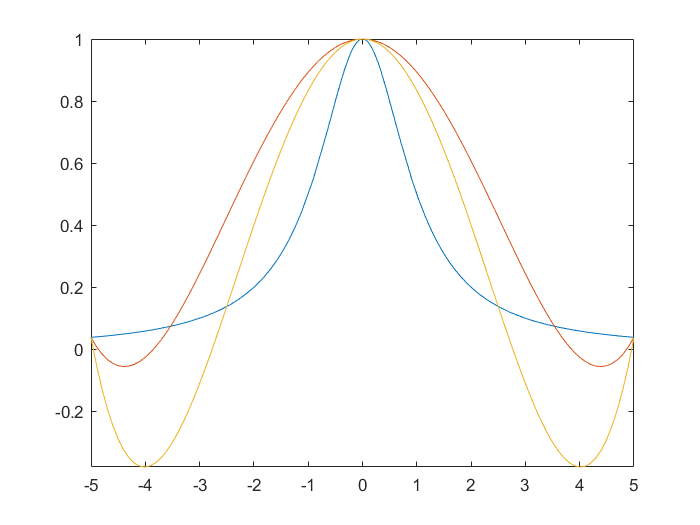

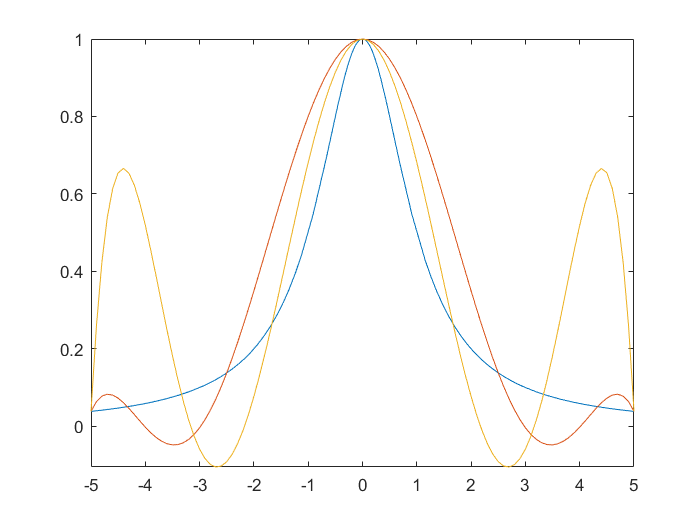

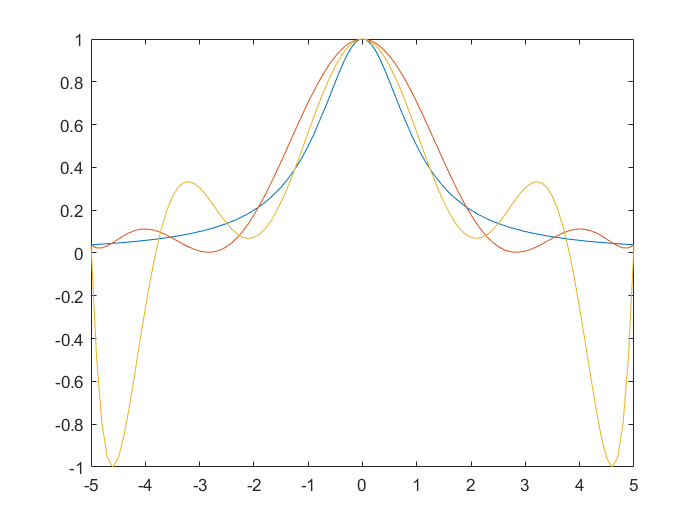

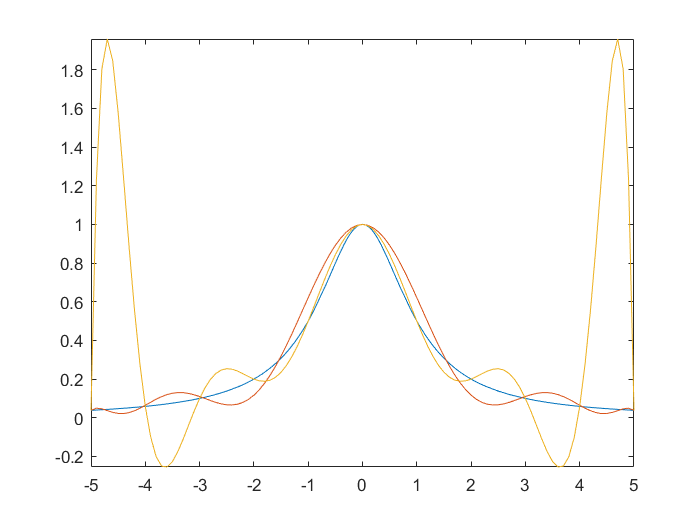

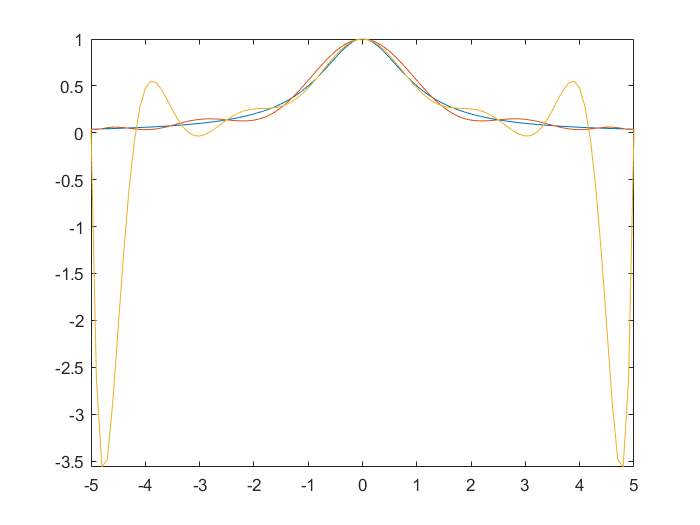

clear
f=@(x) 1./(1+x.^2);
a=-5;b=5;
for n=2:2:12
    figure()
    cv=chebyshev(n,a,b,f);
    x=linspace(a,b,n+1);
    y=f(x);
    p=polyfit(x,y,n);
    fplot(f,[-5 5])
    hold on
    v=-5:0.1:5;
    yc=polyval(cv,v);
    y=polyval(p,v);
    plot(v,yc)
    plot(v,y)
end

esempio

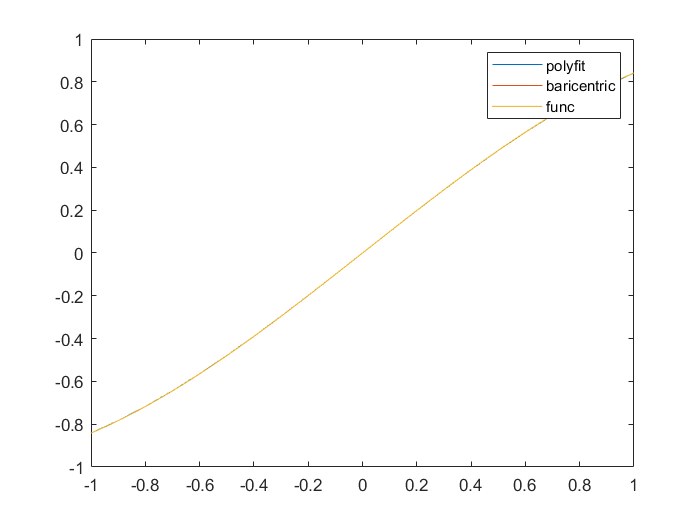

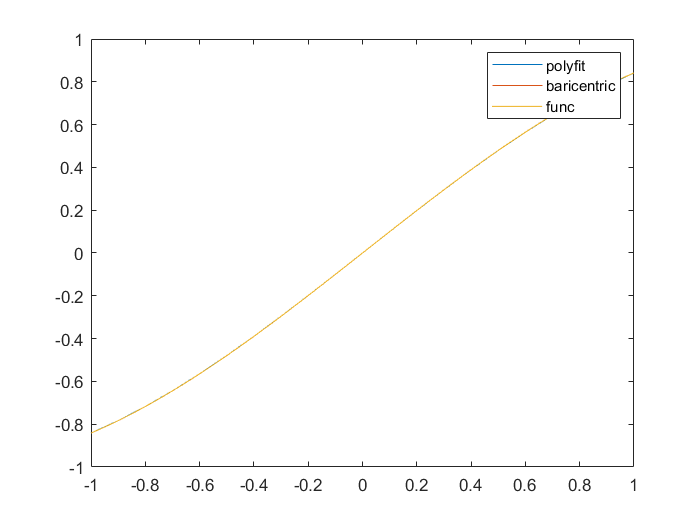

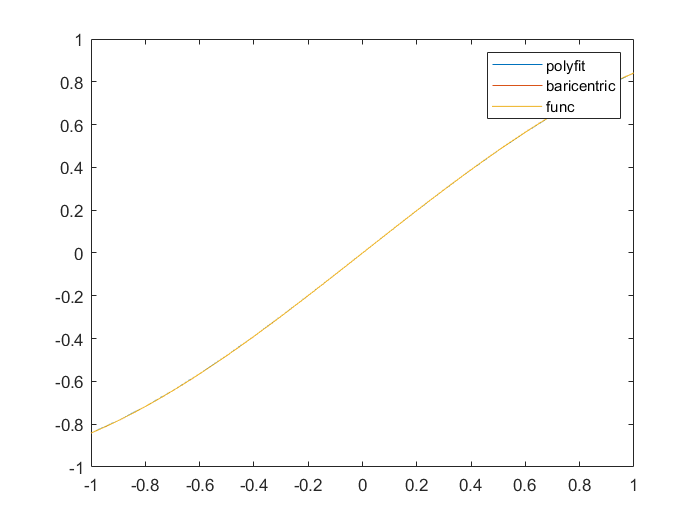

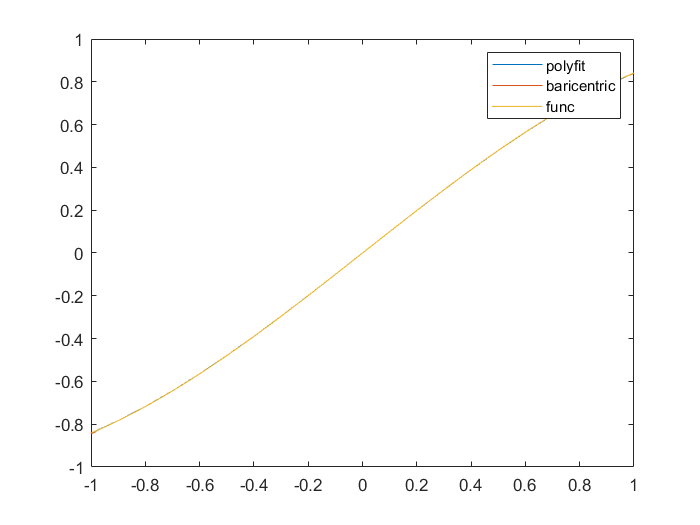

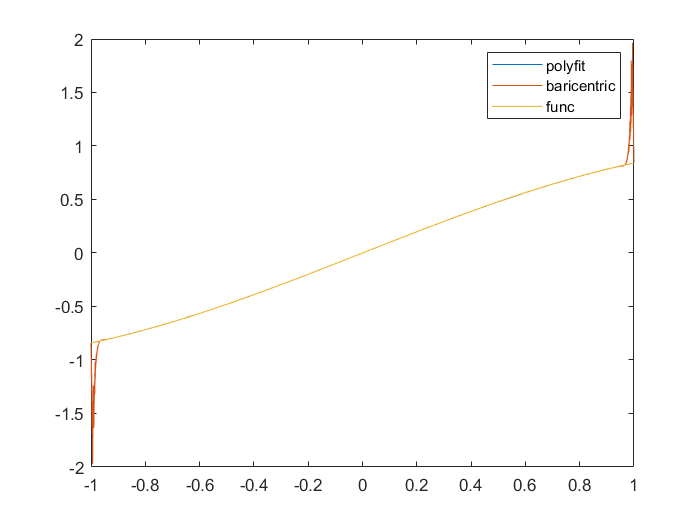

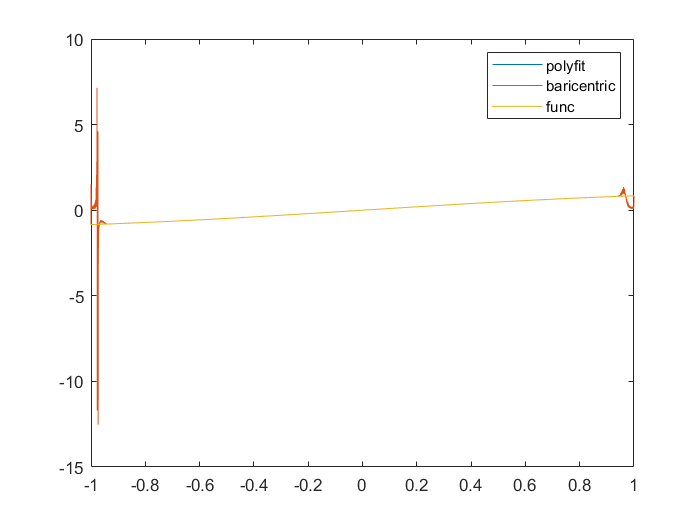

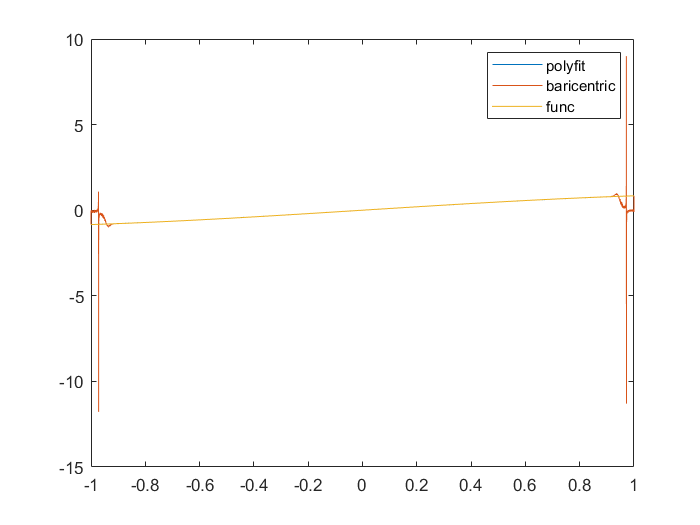

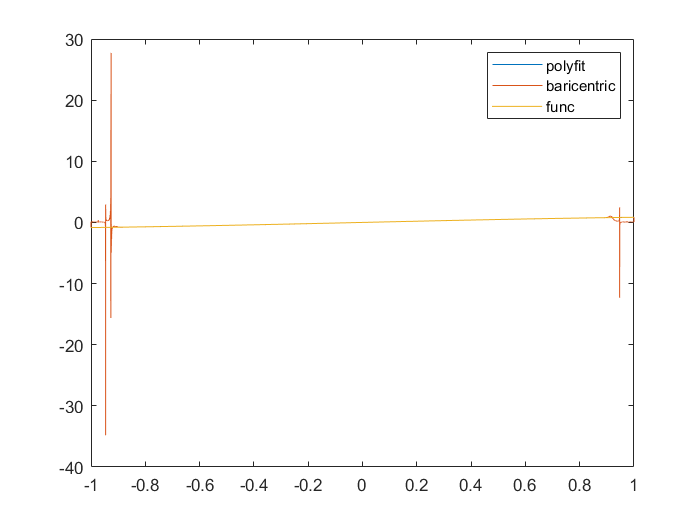

clear
f=@(x) sin(x);
a=-1;b=1;
N=10000;
vn=linspace(a,b,N);
fn=f(vn);
E=[];
Eb=[];
for n=5:5:100
    figure()
    x=linspace(a,b,n+1);
    y=f(x);
    p=polyfit(x,y,n);
    z=a:0.1:b;
    pb=barycentric(x,y,vn);
    
    y=polyval(p,z);
    yb=pb;
    plot(z,y)
    hold on
    plot(vn,yb);
    fplot(f,[a b])
    legend("polyfit","baricentric","func")
    E=[E norm(fn-polyval(p,vn),Inf)];
    Eb=[Eb norm(fn-pb,Inf)];
%     vet=abs(fn-polyval(p,vn))
%     E=[E max(vet)];
%     Eb=[Eb max(fn-polyval(pb,vn))];
end

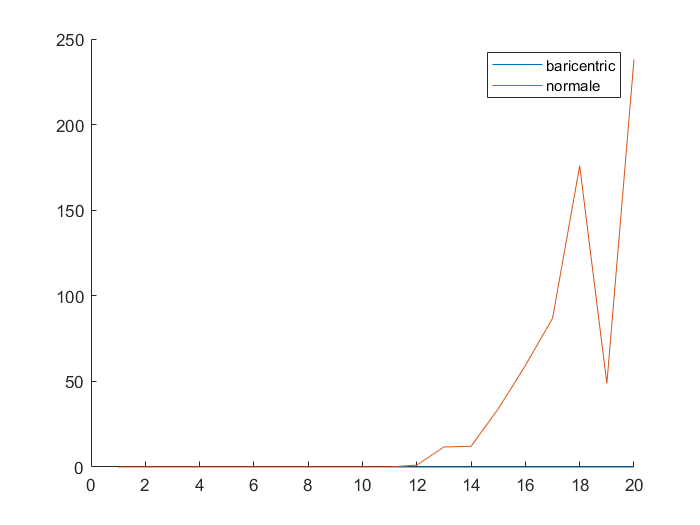

figure()
hold on
plot(E)
plot(Eb)
legend("baricentric","normale")

esercizio 8

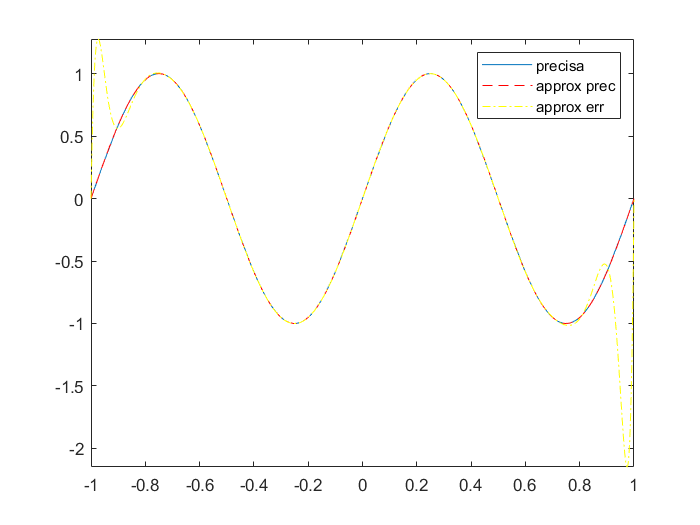

clear 
figure()
f=@(x) sin(2*pi*x);
a=-1;b=1;
n=21;
z=linspace(a,b,n+1);
fr=f(z);
fe=fr-rand(1,n+1)*10^-3;
pr=polyfit(z,fr,n);
pe=polyfit(z,fe,n);
fplot(f,[a b])
hold on
z=linspace(a,b,1000);
yr=polyval(pr,z);
ye=polyval(pe,z);
plot(z,yr,"--r")
plot(z,ye,"-.y")
legend("precisa","approx prec","approx err")

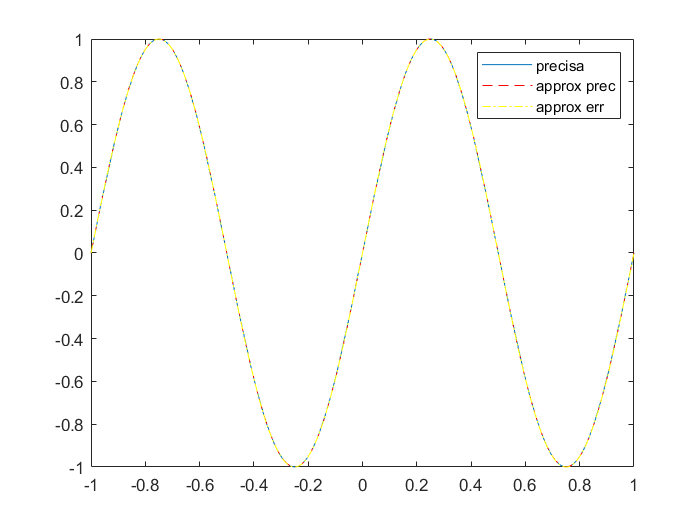

z=(a+b)/2-(b-a)/2*cos(pi*(0:n)/(n));
fr=f(z);
figure()
fe=fr-rand(1,n+1)*10^-3;
pr=polyfit(z,fr,n);
pe=polyfit(z,fe,n);
fplot(f,[a b])
hold on
z=linspace(a,b,1000);
yr=polyval(pr,z);
ye=polyval(pe,z);
plot(z,yr,"--r")
plot(z,ye,"-.y")
legend("precisa","approx prec","approx err")

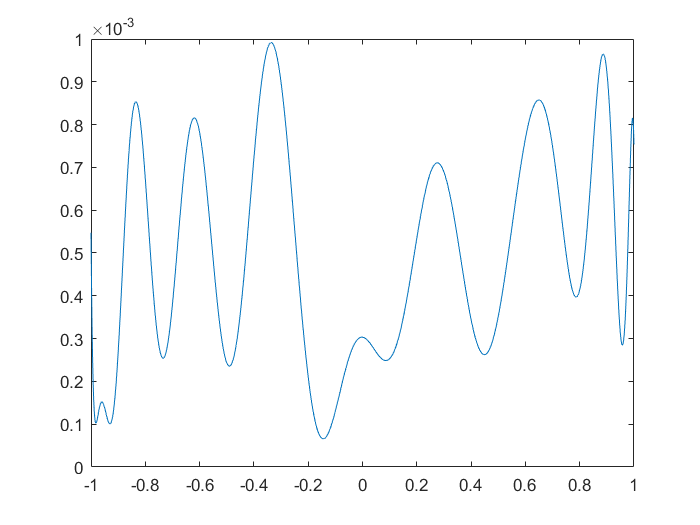

figure()
plot(z,yr-ye)